# Extension Activity: Sportradar API

In this extension activity, you will explore how to use the SportRadar API. The Sportradar API is a free API that requires an API key for accessing its sports database. Their Sports API includes data for the NBA, NFL, NHL, Formula 1, Indycar, soccer, and many other sports leagues!

To get started, follow the link to create an account: [https://developer.sportradar.com/](https://developer.sportradar.com/) 

After creating an account, click on the **Documentation** button in the upper right of your account dashboard to view a table of contents of the available APIs.

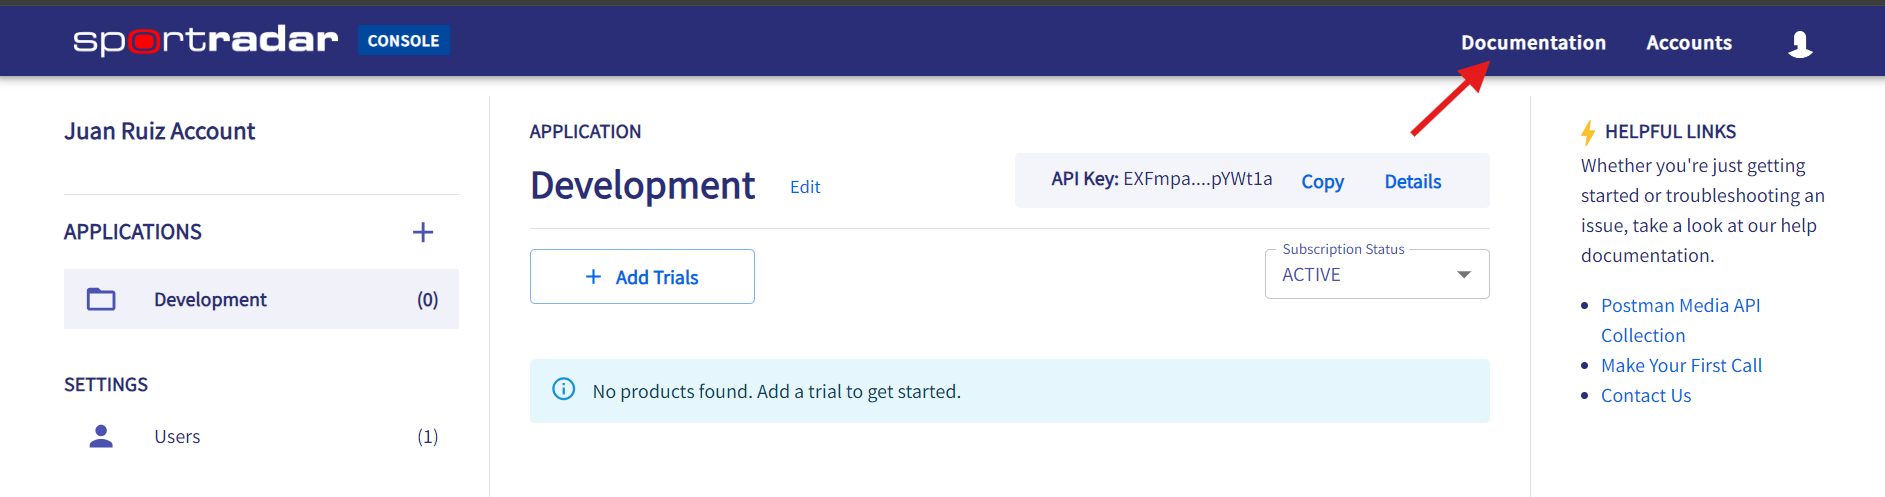

## Getting an API Key

Follow the steps below to get an API Key that will allow you to access the data from Sportradar. Note that you will only get a 30-Day trial valid for 1,000 API calls. In the example below, you will learn how to access the NBA API. For more detailed instructions with images click on **Documentation** and read the **Make Your First Call **section. 

- On your dashboard select **Add Trials.**

- In the **Product Category **select **Sports API.**

- Use the search bar to find the **NBA API. **Then select **Next Step.**

- Lastly **Submit and Create. **

- Copy the **API Key** into the code block below and make note of when your trial ends. 

clc; clear;
% Stores your unique API Key
APIkey = 'your API key goes here';
 

## **Accessing Endpoints**

Click on the **Docs **button to see what endpoints are available. In this example, you will access the **Player Profile **endpoint. Click on this endpoint to open up an interactive window that helps  you create the code necessary to retrieve the desired data. This interactive tool is similar to the one on the Spotify API. Although it doesn't have MATLAB as a built-in language, it is still very useful because it generates the URL needed to retrieve the desired data. To use the interactive tool, copy your API Key into the **Query **text box and set the language to Python since it is  most similar to the format needed for MATLAB. The response generated will not work in MATLAB, but it will provide the basic format needed. If you click **Try It!, **you can see what information you will be able to retrieve in MATLAB. 

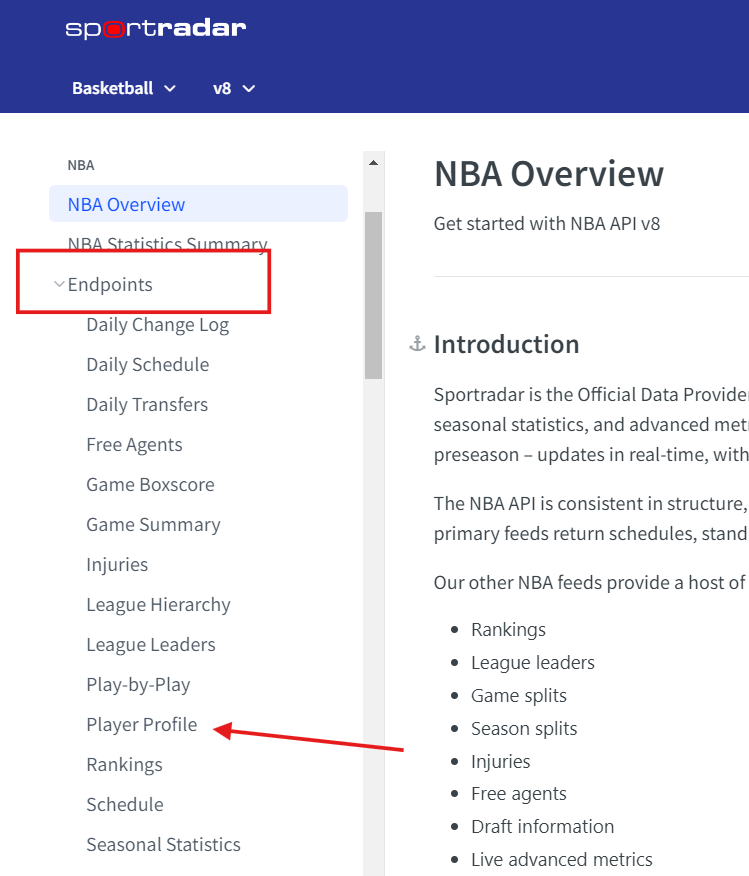                                           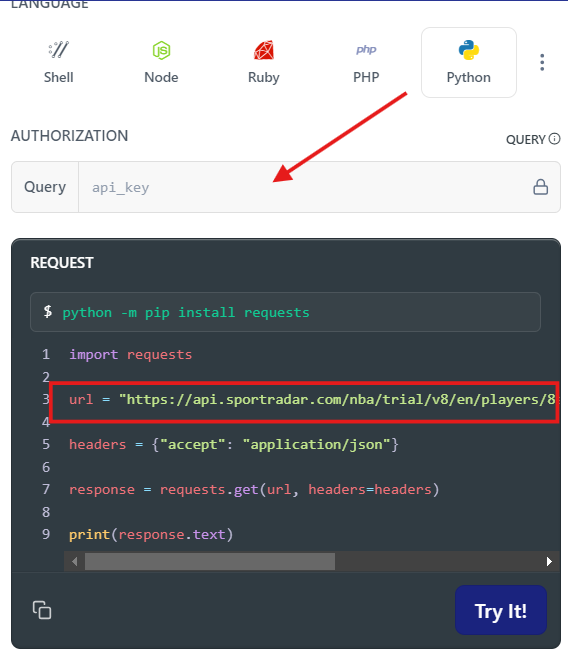

## Finding Player IDs

To retrieve specific player profiles, you need their unique **Player ID. **One way to find **Player IDs **is to start your search within the **Teams **endpoint. This endpoint provides a complete list of active teams in the NBA API database. Input your API key into the interactive tool and click the blue **Try It! **button. The response window will contain the NBA's **League ID** and all the **Team IDs. **

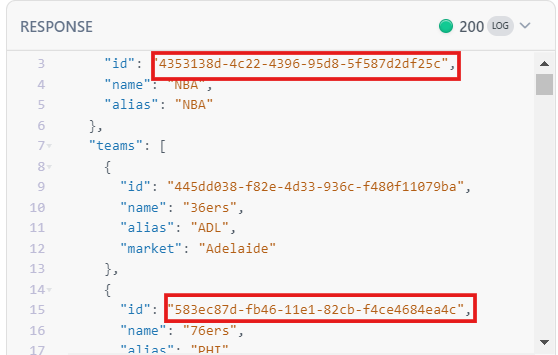

You can scroll down in the **Response **window to find more team IDs. For now, use the **Team ID **for the Golden State Warriors to find the **Player ID** for Stephen Curry. 

- Copy the **Team ID **and go to the **Team Profile **endpoint, which provides team information and a full roster of active players.

- Paste the **Team ID **into the 'team_id' text box to insert it into the interactive tool. 

- Input your **API Key **and click the **Try It!** button. 

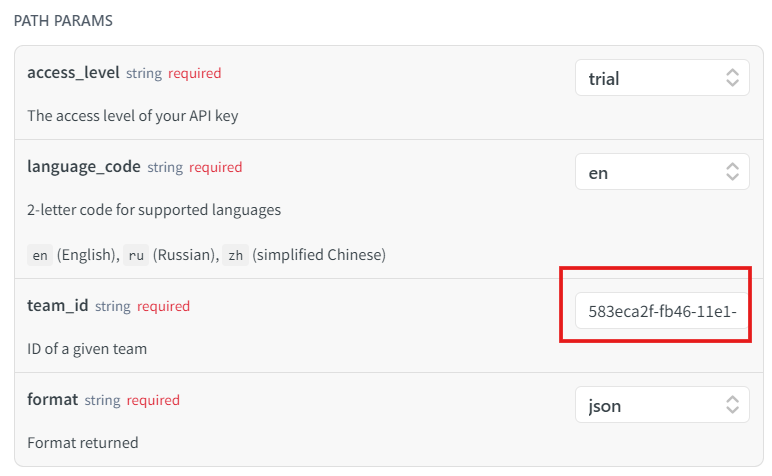

The **Response **window will show all of the team's information, including details about its players. Scroll down to find Stephen Curry's **Player ID**.

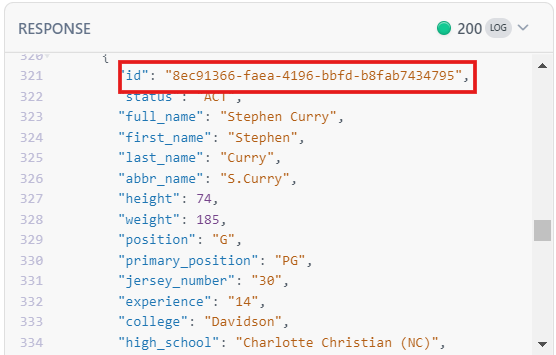

You can follow a similar process to find the **IDs **required to retrieve data in other APIs. It is recommended to always use the interactive tool to search through team profiles in different leagues. Then narrow down your search until you find the **ID **needed to retrieve the information you want. 

## Retrieve the Player's Profile

Let's implement the code necessary to retrieve some information from Curry's player profile. 

The format of the required URL is shown in the image below:

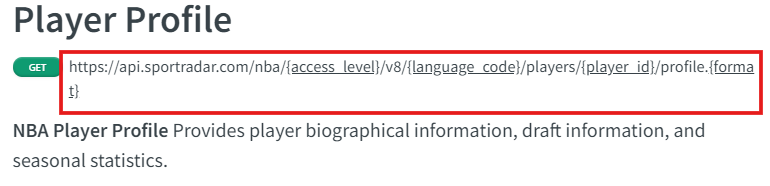

Complete the code below. In the space for access level you will write **"trial"** and for the language code write **"en". **The player ID will be input as the variable **playerID **and the format will be **"json". **Finally, append your API Key at the end of URL using the variable **APIkey. **This format is based on the URL generated by the interactive tool in the Sports API. 

https://api.sportradar.com/nba/{access_level}/v8/{language_code}/players/{player_id}/profile.{format}

% Stores the player ID (Change the player ID)
playerID = '8ec91366-faea-4196-bbfd-b8fab7434795';

% Creates the necessary URL
url = ['https://api.sportradar.com/nba/trial/v8/en/players/', playerID,'/profile.json','?api_key=', APIkey];

% Set the headers
options = weboptions('HeaderFields', {'accept' 'application/json'});

% Make the GET request
response = webread(url, options);
 

At this point, all of the Curry's profile data has been stored in the variable **response. **Click on this variable in the workspace to see what information it contains. When you open the variable you will see the data in the image below. 

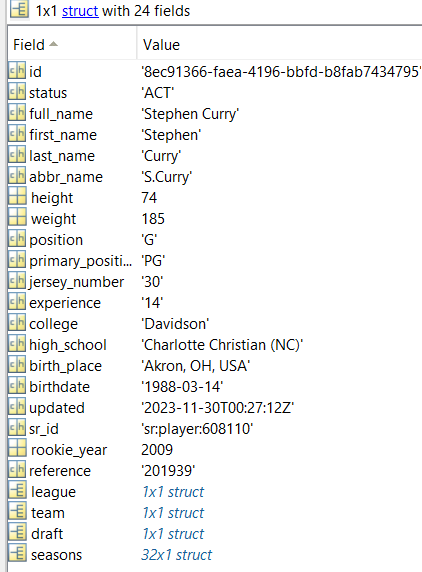

Let's extract some of this data and store it in an Excel file named "Curry_Info.xlsx". Use dot notation to retrieve the desired data from the variable **response**. The dot notation for the height is already included in the code segment below. Look at the image above to figure out the dot notation to retrieved the desired information. 

% First retrieve his height, full name, weight, primary_position, and jersey number.
height = response.height;
name = response.full_name;
weight = response.weight;
position = response.primary_position;
number = response.jersey_number;
exp = response.experience;

% Make a structure using struct() with the data above
player_info = struct('Player', {name},'Experience', {exp}, 'Height', {height},'Weight', {weight}, ...
    'Position', {position}, 'Jersey', {number});

% Make a table and store it as an excel file
writetable(struct2table(player_info), 'Curry_Info.xlsx');
 


The table created only has one row of information, but you can add information from other players to create a larger table.

There is much more information store within the variable **response. **Clicking on **seasons **within the variable brings up all the seasons Curry has played in. Clicking on the 2023 season displays the fields below:

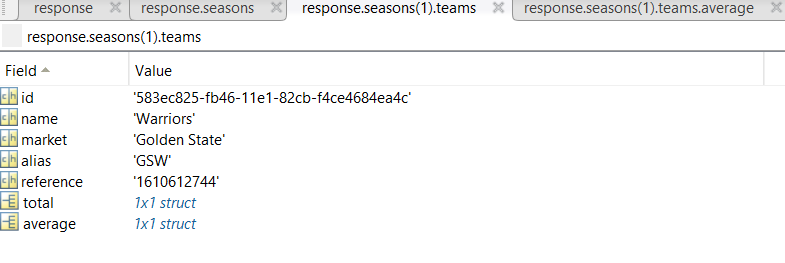

If you click on the **average **struct you will see Curry's average stats per game for the 2023 season.

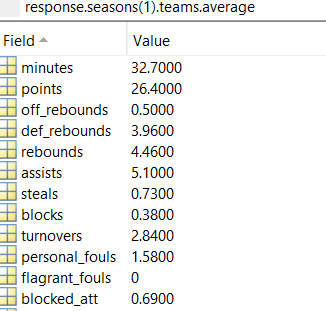

The image below shows the dot notation required to access all of this data. Type in the dot notation into the code block below and store it in the struct called **"CurryAverages"**. Then convert this struct into a table called **"CurryTable"** using **struct2table()**. Lastly, use **rows2vars(CurryTable)** to make the table vertical.

% Retrieves Curry's average stats in 2023
CurryAverages = response.seasons(1).teams.average;

% Convert the CurryAverages into a table using struct2table()
CurryTable = struct2table(CurryAverages);

% Make CurryTable into a one column table
CurryTable = rows2vars(CurryTable);

% display the table using disp()
disp(CurryTable)

     OriginalVariableNames      Var1 
    ________________________    _____

    {'minutes'             }     32.7
    {'points'              }     26.4
    {'off_rebounds'        }      0.5
    {'def_rebounds'        }     3.96
    {'rebounds'            }     4.46
    {'assists'             }      5.1
    {'steals'              }     0.73
    {'blocks'              }     0.38
    {'turnovers'           }     2.84
    {'personal_fouls'      }     1.58
    {'flagrant_fouls'      }        0
    {'blocked_att'         }     0.69
    {'field_goals_made'    }     8.78
    {'field_goals_att'     }    19.53
    {'three_points_made'   }     4.82
    {'three_points_att'    }    11.84
    {'free_throws_made'    }     4.04
    {'free_throws_att'     }     4.38
    {'two_points_made'     }     3.96
    {'two_points_att'      }     7.69
    {'efficiency'          }     23.2
    {'true_shooting_att'   }    21.45
    {'points_off_tu

## Summary

In this Extension Activity, you were introduced to the Sportsradar Sports API, which contains lots of data on a variety of sport leagues. You are encouraged to keep exploring the other endpoints available under the NBA API or any other API within Sportsradar. When exploring through a new Sports API, use the interactive tool provided by Sportsradar to identify what information it can provide before you start writing the code in MATLAB. This approach will help you save time when exploring new APIs.